data = readtable('data_reduced.csv')

data = 328×47 table
    Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    matrixSTRENGTH    matrixStrainbreak    matrixImpact    impurityE    impuritySTRENGTH    impurityStrainbreak    impurityImpact    matrixXc    impurityXc    blendE    blendSTRENGTH    blendStrainbreak    blendImpact    MajorityPolymer_H

lables= data.Properties.VariableNames

lables = 1×47 cell array
    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'matrixSTRENGTH'}    {'matrixStrainbreak'}    {'matrixImpact'}    {'impurityE'}    {'impuritySTRENGTH'}    {'impurityStrainbreak'}    {'impurityImpact'}    {'matrixXc'}    {'impurityXc'}    {'blendE'}    {'blendSTRENGTH'}    {'blendStrainbreak'}    {'blendImpact'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'Min

lables = cell2table(lables);
lablesS = lables(1, 1:13);
lablesS2 = lables(1,28:end);
%so important two features are 14 matrixE, 18 impurityE and 13 %mix; in
%reduced table cols (13-15)
lablesE= [lablesS, lables(1,14), lables(1,18), lables(1,22:23), lablesS2];
lablesYE= lables(1,24);
% skipping  Strenth Impact Strain Break
E =  table2array(data(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

E = 1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020  


% normalize to range 0-1 
Xe= [E(:,1:17), E(:,19:end)];
Ye = E(:,18)./max(E(:,18)); 

cols_continuous_norm = Xe(:,14:17) ./ max(Xe(:,14:17))

cols_continuous_norm =     0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601         0    0.4860         0
    0.0601    0.0355    0.4860    0.4281
    0.0601    0.0355    0.4860    0.4281
    0.0601    0.0355    0.4860    0.4281


Xe(:,14:17)= cols_continuous_norm;


pd =   WeibullDistribution

  Weibull distribution
    A = 0.479102   [0.436005, 0.526459]
    B =  1.20096   [1.0942, 1.31813]


h = 1

Only two vars are continuous 14/15 and 16/17

chisquare test for normal distribution = none cols are!!

% Set the significance level (alpha)
alpha = 0.05;
[rows,cols] = size(data);

results =  struct('hyp', h, 'pval', p);

for i = 1:cols
    columnData = table2array(data(:, i));
    [h, p] = chi2gof(columnData, 'cdf', @(x) normcdf(x, mean(columnData), std(columnData)), 'Alpha', alpha);
    results(i).hyp = h
    results(i).pval = p
end


% Display the results for each column
for i = 1:cols
    fprintf('Column %d:\n', i);
    if results(i).hyp == 0
        fprintf('The data follows a normal distribution.\n');
    else
        fprintf('The data does not follow a normal distribution.\n');
    end
    fprintf('p-value: %.4f\n', results(i).pval);
    fprintf('\n');
end

Performing Student ttest  -> DOES NOT WORK BC normal dist assumption!!!

intially a lean of 0 was tested but the hypotheiss was rejectedn witha  99% significance level 

thus testing for a higher mean ( right tail ) is proceded, with amean of 1, the hypotheiss null was accepted 

populationMean = 2;
alpha = 0.01; 

% Perform the one-sample t-test
%h = ttest(cols_continuous_norm(:,1), populationMean, 'Alpha', alpha);
[h, p, ci, stats] = ttest(cols_continuous_norm, populationMean, 'Alpha', alpha, 'Tail','left');

% 'h' indicates whether the null hypothesis is rejected (1) or not (0)
% 'p' is the p-value of the test
% 'ci' is the confidence interval for the mean difference
% 'stats' contains additional statistics such as the t-value and degrees of freedom

% Display the results
disp(['Null Hypothesis Rejected (h): ' num2str(h)]);

Null Hypothesis Rejected (h): 1  1  1  1


disp(['p-value: ' num2str(p)]);

p-value: 7.088e-229 1.1114e-221 9.8827e-229 2.5399e-223


disp(['Confidence Interval: ' num2str(ci(1,:))]);

Confidence Interval: -Inf -Inf -Inf -Inf


disp(['T-Statistic: ' num2str(stats.tstat)]);

T-Statistic: -87.2588     -82.7582     -87.1663     -83.7656


disp(['Degrees of Freedom: ' num2str(stats.df)]);

Degrees of Freedom: 327  327  327  327


disp(['std estimated' num2str(stats.sd)])

std estimated0.32092     0.35198     0.30232     0.34117


Q-Q Plot: Create a quantile-quantile (Q-Q) plot to compare the quantiles of your data against the quantiles of a theoretical normal distribution. The straight line indicates how normally dstributed wouldbe. AS we can see the tails are much more present than in normal dist. 

BOX PLOT: the median is at 0.5, it shows the normalized data between 0 ane 1 with teh whiskers, no outliers detected. the IQR goes form 01  to 0.7, so  4th quartile goes from 0.71-1, >0.25, thus the 4th quartile contiqns less instances as it spams more ranges. 

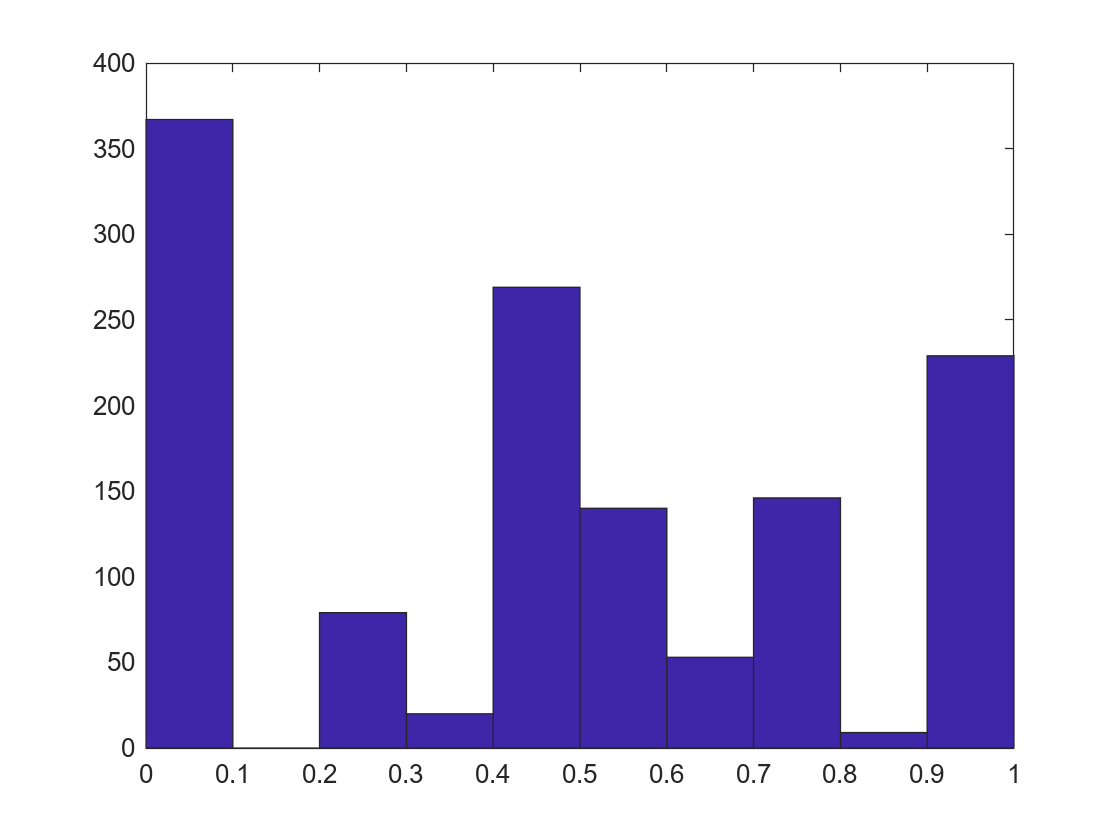

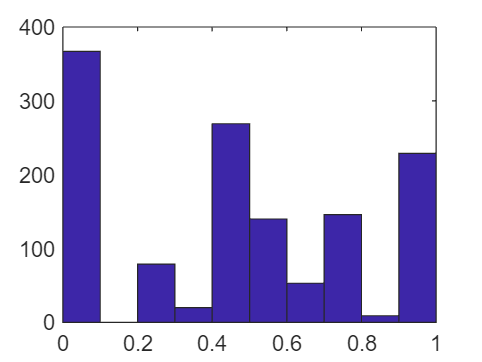

dataArray = reshape(cols_continuous_norm, 1, []);
hist(dataArray)

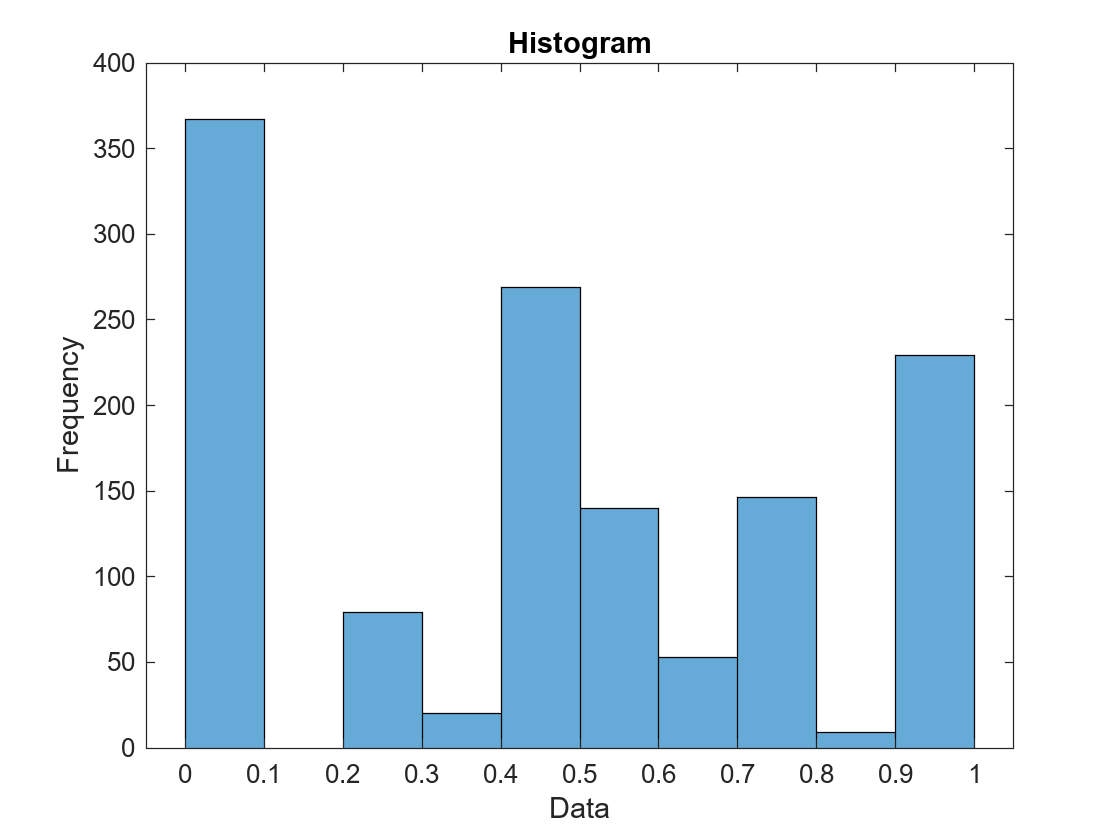


% Histogram
figure;
histogram(dataArray);
title('Histogram');
xlabel('Data');
ylabel('Frequency');

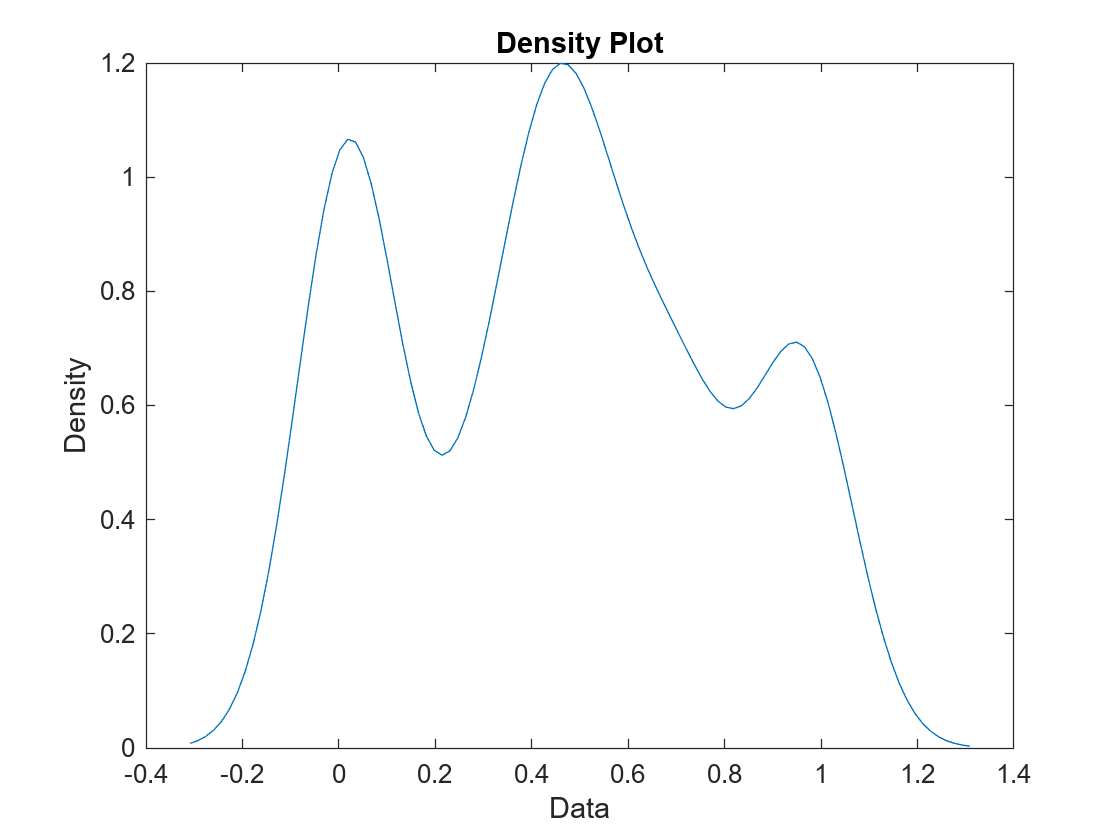


% Density Plot
figure;
ksdensity(dataArray);
title('Density Plot');
xlabel('Data');
ylabel('Density');

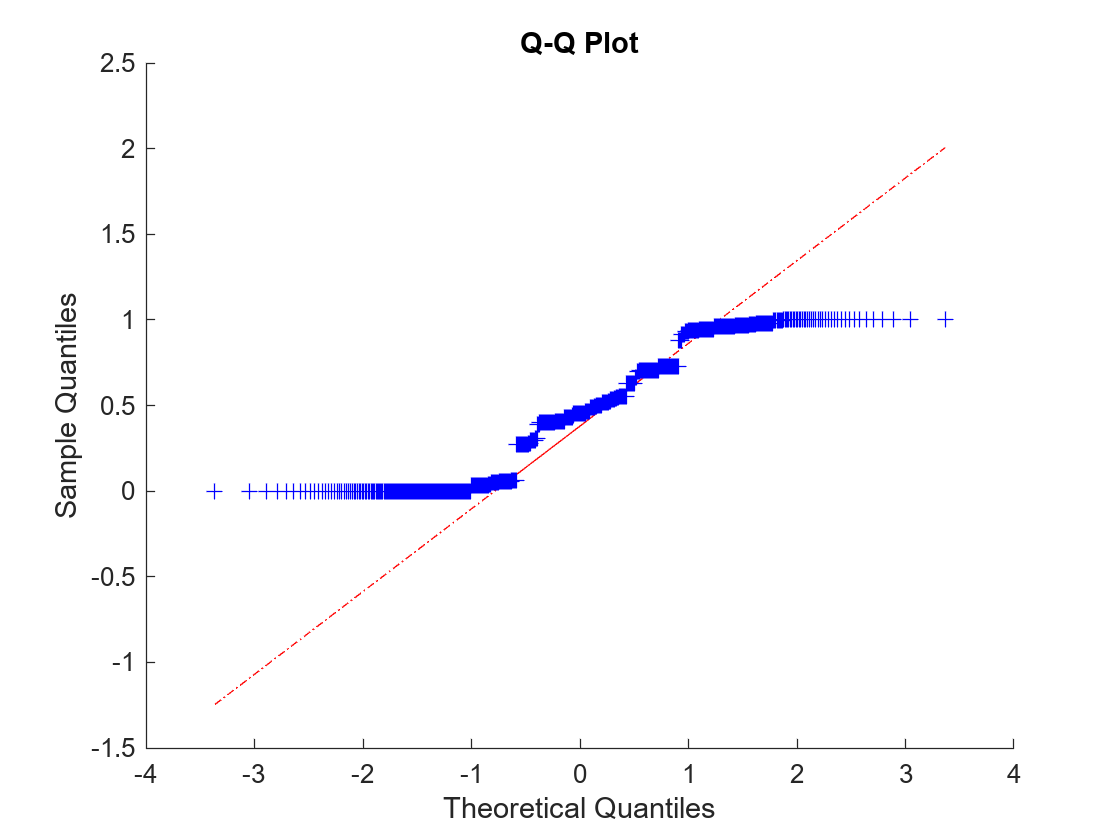


% Q-Q Plot
figure;
qqplot(dataArray);
title('Q-Q Plot');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');


% Box Plot
figure;
boxplot(dataArray);

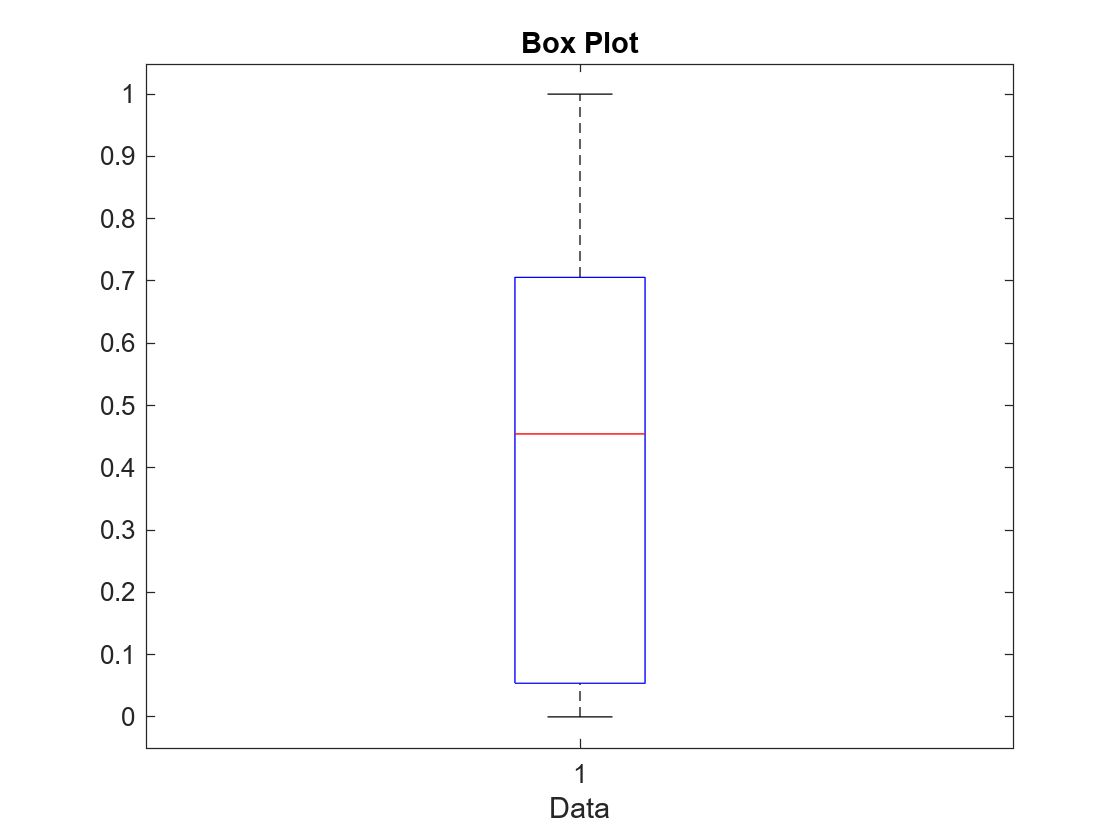

title('Box Plot');
xlabel('Data');

KDE (kernel density function) etimate underlying PDF of dta. With smoothing function. Plotting only the traininga nd target instances, we get very similar PDFS however, while adding the individuak instances as a normal func( assumption of GP to find the best normal func) the scale does not show all lines, the difference is too much -> add padding but still the target PDF is np longer visible 

pdTarget = fitdist(Ye,'Kernel','Width',10);
pdTrain = fitdist(dataArray','Kernel','Width',10);
x = 0:.001:1;
yPDF = pdf(pdTarget,x)

yPDF =     0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398


xPDF = pdf(pdTrain, x)

xPDF =     0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398    0.0398



figure
plot(x,yPDF,'k-','LineWidth',2)
hold on
plot(x,xPDF,'r-','LineWidth',2)

%adding padding to see all lines 
mini = 100;
%too many for all instance, only plot around 10
 for i=1:100:length(dataArray)
     pd = makedist('Normal','mu',dataArray(i),'sigma',0.09);
     y = pdf(pd,x);
     y = y/length(dataArray);
     %compute the min 
     if mini > y
         mini = y; 
     end 
     plot(x,y,'b:')
 end
yMin = min(mini) -0.1*abs(min(mini))

yMin = 6.3078e-27

yMax = max(xPDF) + 0.1* max(xPDF)

yMax = 0.0439

yRange = [yMin, yMax]

yRange =     0.0000    0.0439


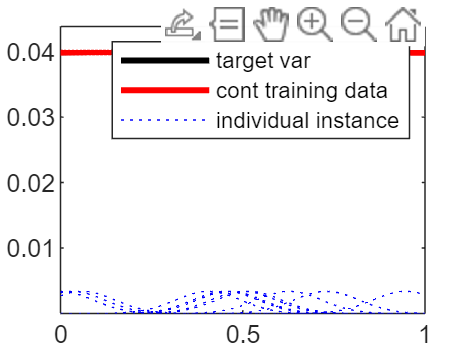

ylim(yRange)
legend({'target var', 'cont training data', 'individual instance'})
hold off

Trying differnet kernels SMOOTTHING FUNCTIONS    

box is much less smooth than the otehrs

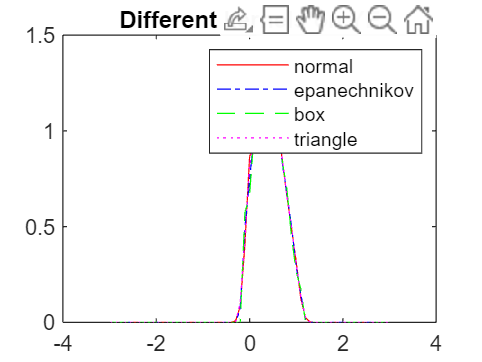

% Set plot specifications
hname = {'normal' 'epanechnikov' 'box' 'triangle'};
colors = {'r' 'b' 'g' 'm'};
lines = {'-','-.','--',':'};

% Generate a sample of each kernel smoothing function and plot
figure
for j=1:4
    pd = fitdist(Ye,'kernel','Kernel',hname{j});
    x = -3:.1:3;
    y = pdf(pd,x);
    plot(x,y,'Color',colors{j},'LineStyle',lines{j})
    hold on
end
title('Different kernels on YE')
legend(hname)
hold off


pd = fitdist(Ye, 'normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0.419782   [0.388274, 0.451289]
    sigma = 0.290061   [0.269432, 0.314137]


h = chi2gof(Ye, 'CDF', @unifcdf)

h = 1

%target is also not normally distributed 

added the kde density previously found, the normal smoothin function is the one that best approx to the estimated KDE. 

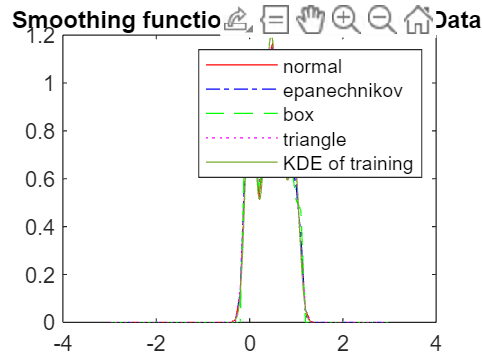

% Set plot specifications
hname = {'normal' 'epanechnikov' 'box' 'triangle', 'KDE of training'};
colors = {'r' 'b' 'g' 'm'};
lines = {'-','-.','--',':'};

% Generate a sample of each kernel smoothing function and plot
figure
for j=1:4
    pd = fitdist(dataArray','kernel','Kernel',hname{j});
    x = -3:.1:3;
    y = pdf(pd,x);
    plot(x,y,'Color',colors{j},'LineStyle',lines{j})
    hold on
end
ksdensity(dataArray)
title('Smoothing functions on Continuous Data ')
legend(hname)
hold off

%assesing different lengthsacles: normal kernel smoothing function 
pd1 = fitdist(dataArray','kernel');
pd5 = fitdist(dataArray', 'kernel', 'Width', 0.01)

pd5 =   KernelDistribution

    Kernel = normal
    Bandwidth = 0.01
    Support = unbounded


pd2 = fitdist(dataArray','kernel','Width',1);
pd3= fitdist(dataArray','kernel','Width',10);
pd4 = fitdist(dataArray','kernel','Width',20);

% Compute each pdf
x = 0:0.001:1;
y1 = pdf(pd1,x);
y2 = pdf(pd2,x);
y3 = pdf(pd3,x);
y4 = pdf(pd4, x)

y4 =     0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199


y5 = pdf(pd5, x)

y5 =     6.3027    6.2745    6.1854    6.0385    5.8386    5.5920    5.3062    4.9898    4.6517    4.3013    3.9475    3.5990    3.2638    2.9486    2.6595    2.4004    2.1748    1.9848    1.8309    1.7129    1.6294    1.5785    1.5569    1.5614    1.5884    1.6340    1.6942    1.7652    1.8435    1.9258    2.0093    2.0918    2.1714    2.2470    2.3178    2.3836    2.4447    2.5017    2.5554    2.6066    2.6563    2.7038    2.7530    2.8020    2.8506    2.8983    2.9441    2.9865    3.0240    3.0545


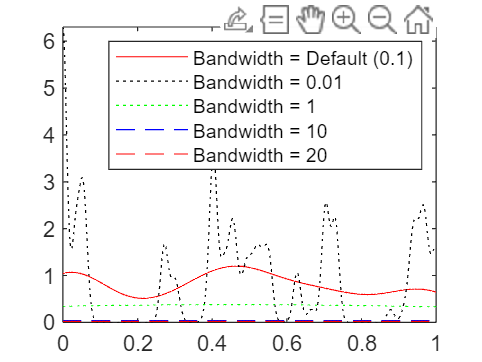

% Plot each pdf
plot(x,y1,'Color','r','LineStyle','-')
hold on
plot(x, y5, 'Color','k','LineStyle',':')
plot(x,y2,'Color','g','LineStyle',':')
plot(x,y3,'Color','b','LineStyle','--')
plot(x,y4,'Color','r','LineStyle','--')
hold off
legend({'Bandwidth = Default (0.1)','Bandwidth = 0.01','Bandwidth = 1','Bandwidth = 10', 'Bandwidth = 20'})

STAts tests to test how off to normal dist. with mean = 0.5 and std = 0.3 it teh null hypothesis is rejected and non paramterize too. 

REJECTED DIST : lognormal, normal, extreme vales, weibull and exponnetia 

dist = makedist('normal','mu',0.5,'sigma',0.3)

dist =   NormalDistribution

  Normal distribution
       mu = 0.5
    sigma = 0.3


[h,pA] = adtest(dataArray,'Distribution',dist)

h = logical
   1


pA = 4.5732e-07

disp(['ADtest,norm dist rejected?: ' num2str(h)]);

ADtest,norm dist rejected?: 1


% Anderson-Darling Test
[h, p, stats] = adtest(dataArray)

h = logical
   1


p = 5.0000e-04

stats = 33.1466

disp(['Anderson-Darling Test - p-value: ' num2str(p)]);

Anderson-Darling Test - p-value: 0.0005


disp(['Statistic: ' num2str(stats)]);

Statistic: 33.1466


[hEv,pEv] = adtest(dataArray,'Distribution','ev')

hEv = logical
   1


pEv = 5.0000e-04

disp(['AD H0rejection - for extreme values dist: ' num2str(hEv)]);

AD H0rejection - for extreme values dist: 1


[hLn,pLn] = adtest(dataArray,'Distribution','logn')

hLn = logical
   1


pLn = 0

disp(['AD H0rejection- log normal dist: ' num2str(hLn)])

AD H0rejection- log normal dist: 1


[hW,pW] = adtest(dataArray,'Distribution','weibull')

hW = logical
   1


pW = 0

disp(['ADH0rejection - weibull dist : ' num2str(hW)])

ADH0rejection - weibull dist : 1


[hE,pE] = adtest(dataArray,'Distribution','exp')

hE = logical
   1


p = 5.0000e-04

disp(['AD H0rejection- exponential dist: ' num2str(hE)])

AD H0rejection- exponential dist: 1


TEsting for many dists!! of the only two continuous columsns

distributions = { 'normal', 'exponential', 'poisson', 'binomial', 'gamma', 'weibull','beta', 'Generalized Extreme Value','Half Normal' ,'InverseGaussian','Kernel', 'tLocationScale', 'Stable' , 'Burr', 'BirnbaumSaunders','Logistic', 'Nakagami', 'Rayleigh', 'Rician' };
   numDistributions = numel(distributions);
    fitTestResultsElas = struct('Distribution', distributions, 'rejection', zeros(numDistributions, 1));
     fitTestResultsSB = struct('Distribution', distributions, 'rejection', zeros(numDistributions, 1));
  xElas = Xe(:,14);
 xS=  Xe(:,16)

xS =     0.4860
    0.4860
    0.4860
    0.4860
    0.4860
    0.4860
    0.4860
    0.4860
    0.4860
    0.4860


    for i = 1:numDistributions
        distribution = distributions{i};
     
        switch distribution
            case 'uniform'
                % pd = fitdist(x, 'normal')
                % h = chi2gof(x, 'CDF', @unifcdf);
            case 'normal'
                pd = fitdist(xElas, 'normal');
                hE= chi2gof(xElas, 'CDF', pd);
                pdS = fitdist(xS, 'normal');
                hS= chi2gof(xS, 'CDF', pdS);
            case 'exponential'
                pd = fitdist(xElas, 'Exponential');
                 hE= chi2gof(xElas, 'CDF', pd);
                  pdS = fitdist(xS, 'Exponential');
                 hS= chi2gof(xS, 'CDF', pdS); 
            case 'poisson'
                pd = fitdist(xElas, 'Poisson');
                 hE= chi2gof(xElas, 'CDF', pd);
                 pdS = fitdist(xS, 'Poisson');
                 hS= chi2gof(xS, 'CDF', pdS);
            case 'binomial'
                pd = fitdist(xElas, 'Binomial');
                 hE= chi2gof(xElas, 'CDF', pd);
                   pdS = fitdist(xS, 'Binomial');
                 hS= chi2gof(xS, 'CDF', pdS);
            case 'gamma'
                pd = fitdist(xElas, 'Gamma');
                 hE= chi2gof(xElas, 'CDF', pd);
                   pdS = fitdist(xS, 'Gamma');
                 hS= chi2gof(xS, 'CDF', pdS);
             % case 'BirnbaumSaunders'
             %    pd = fitdist(x, 'BirnbaumSaunders');
             %     h= chi2gof(x, 'CDF', pd);
              % case 'Burr'
              %   pd = fitdist(x, 'Burr');
              %    h= chi2gof(x, 'CDF', pd);
             case 'beta'
                pd = fitdist(xElas, 'Beta');
                 hE= chi2gof(xElas, 'CDF', pd);
                   pdS = fitdist(xS, 'Beta');
                 hS= chi2gof(xS, 'CDF', pdS);
             case 'Extreme Value'
                pd = fitdist(xElas, 'Generalized Extreme Value');
                 hE= chi2gof(xElas, 'CDF', pd);
                   pdS = fitdist(xS, 'GeneralizedExtremeValue');
                 hS=  chi2gof(xS, 'CDF', pdS);
            case 'Half Normal' 
                pd = fitdist(xElas, 'Half Normal');
                 hE= chi2gof(xElas, 'CDF', pd);
                   pdS = fitdist(xS, 'Half Normal');
                 hS = chi2gof(xS, 'CDF', pdS);
            % case 'InverseGaussian'
            %     pd = fitdist(xElas, 'InverseGaussian');
            %      h= chi2gof(xElas, 'CDF', pd);
            case 'Kernel'
                 pd = fitdist(xElas, 'Kernel');
                 hE= chi2gof(xElas, 'CDF', pd);
                   pdS = fitdist(xS, 'Kernel');
                 hS= chi2gof(xS, 'CDF', pdS);
            case 'tLocationScale'
                 pd = fitdist(xElas, 'tLocationScale');
                 hE= chi2gof(xElas, 'CDF', pd);
                   pdS = fitdist(xS, 'tLocationScale');
                 hS= chi2gof(xS, 'CDF', pdS);
            case 'Stable'
                 pd = fitdist(xElas, 'Stable');
                 hE= chi2gof(xElas, 'CDF', pd);
                 pdS = fitdist(xS, 'Stable');
                 hS= chi2gof(xS, 'CDF', pdS);
            % case 'Rician'
            %     pd = fitdist(x, 'Rician');
            %      h= chi2gof(x, 'CDF', pd);
            case 'Rayleigh'
                pd = fitdist(xElas, 'Rayleigh');
                 hE= chi2gof(xElas, 'CDF', pd);
                 pdS = fitdist(xS, 'Rayleigh');
                 hS= chi2gof(xS, 'CDF', pdS);
              % case 'Nakagami'
              %   pd = fitdist(x, 'Nakagami');
              %    h= chi2gof(x, 'CDF', pd);
         case 'Logistic'
                pd = fitdist(xElas, 'Logistic');
                 hE= chi2gof(xElas, 'CDF', pd);
                 pdS = fitdist(xS, 'Logistic');
                 hS= chi2gof(xS, 'CDF', pdS);
        end
        fitTestResultsElas(i).rejection =hE;
        fitTestResultsSB(i).rejection = hS;
    end

fitTestResultsElas.rejection

ELas = 1

fitTestResultsSB.rejection

SB = 1